close all;
clc;
%f=@(x) sin(pi*x);

syms x;
%Data
%Input data
n=input('Enter no. of node points:');                %no. of node points
%enter x values
a=input('Enter the values of x in braces:');
if length(a)==n
b=input('Enter the values of y in braces:');
%calculation of coeffiecients
for i=1:n
    for j=1:n
        c.c(i,j)=(a(1,i)-a(1,j));
    end
end
c=c.c;
q=size(c);
c=c';
c(c==0)=[];                  %deleting the zero values from the matrix
c=reshape(c,q(2)-1,q(1));
c=c';
j=1;
for i=1:n
    d.d(i,j)=prod(c(i,:));
end
d=d.d;
d=d';
for i=1:n
    coff.coff(i,j)=b(1,i)./d(1,i);
end
coff=coff.coff;
coff=coff';                                  %coefficients

for i=1:n
    for j=1:n
        p.p(i,j)=(x-a(1,j));
    end
end
p=p.p;
m=size(p);
p=p';
p(1:n+1:end)=[];                     %deleting the diagonal elements
p=reshape(p,m(2)-1,m(1));

p=prod(p);
pol=coff.*p;                            
pol=sum(pol);                                %Lagrange polynomial

l=input('Enter a value to compute the b value:');
output=subs(pol,l);

%Displaying output
disp('');
fprintf('Value of input x:=%f\n',double(output));

Value of input x:=17.877143


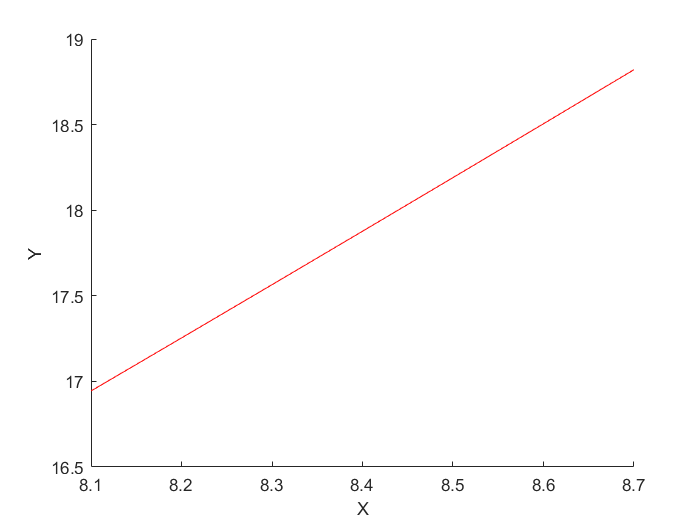

hold on

if l>max(a)
    x=min(a):0.1:l;
    y=subs(pol,x);
    plot(x,y,'r');
    xlabel('X')
    ylabel('Y')
else
    x=min(a):0.1:max(a);
    y=subs(pol,x);
    plot(x,y,'r');
    xlabel('X')
    ylabel('Y')
end

%fplot(f)
%hold off
else
    display('Error: Values of x exceeds the number of node points')
end
%End of code